# The typical drEEM workflow

[Run this tutorial as a Live script.](matlab:open('dreem_workflow.mlx'))

Let's assume you have the drEEM toolbox installed and you've just completed measurements for a new set of data. We think the following workflow could be used at the beginning of every new script.

## Initialize the workspace

First, let's initialize the Matlab workspace.

clearvars
close all
cd(fileparts(matlab.desktop.editor.getActiveFilename))

These three lines give us a fresh start. First, `clearvars` deletes all variables in the current workspace. The call `close all` then closes all figures. This will ensure that you always start without potential conflicts from existing variables and that you won't mistake some old figure for new output.

The next line `cd(fileparts(matlab.desktop.editor.getActiveFilename))` changes the current directory to the directory in which the m-file is saved in. This means the script could be copied and pasted into a different directory to work on the next project without modifications. This has proved very useful in our laboratory standard practices!

## Initialize the toolbox

Next, let's initialize the toolbox.

installdreem

drEEM is up to date


tbx=drEEMtoolbox;

Let's make sure that drEEM is installed and up-to-date with a call to `installdreem`. If that fails with an error, you don't have the toolbox installed properly.  Look for the `installdreem` m-file on your hard-drive and run it in Matlab. It might simply be invisible to Matlab because it is not in the current Matlab path (take a look with a call to `path` to troubleshoot).

Next, the drEEMtoolbox is initialized as an object. You could call this object any name you like. Here, we've chosen `tbx` as a shorthand for "toolbox". 

This is it. A typical script using the drEEM toolbox could always start as shown until this point. In summary:

clearvars %  clear all existing variables
close all %  close all existing figures
cd(fileparts(matlab.desktop.editor.getActiveFilename)) % change the current directory to the one containing this script
installdreem % make sure the drEEM toolbox is installed and up-to-date.

drEEM is up to date


tbx=drEEMtoolbox; % assign an object to call the toolbox functions.

## Some information on the drEEMtoolbox object

disp(tbx)

  drEEMtoolbox with properties:

       version: "2.0.0"
           url: "https://gitlab.com/dreem/dreem-2.0"
    rootfolder: '/Users/urban/Documents/MATLAB/drEEM-2.0/'



tbx has several *properties* and *methods*. For the toolbox, properties tell you some details about the toolbox itself like version, project URL and where on the hard-drive the toolbox is located.

Far more interesting are the *methods*. These are the functions available to you that load, modify, and analyze the data. Let's get an overview ...

list=methods(tbx);
disp(categorical(list))

     addcomment 
     addlistener 
     alignsamples 
     associatemetadata 
     benchmark 
     changestatus 
     delete 
     displayhistory 
     drEEMtoolbox 
     dreemfig 
     dreemuifig 
     eq 
     explorevariability 
     export2netcdf 
     export2openfluor 
     exportresults 
     findobj 
     findprop 
     fitparafac 
     fitslopes 
     ge 
     gt 
     handlescatter 
     help 
     ifecorrection 
     importabsorbance 
     importeems 
     isvalid 
     le 
     listener 
     lt 
     ne 
     notify 
     pickpeaks 
     processabsorbance 
     ramancalibration 
     reportresidualanalysis 
     rmbackups 
     rmspikes 
     scalesamples 
     spectralvariance 
     splitdataset 
     splitvalidation 
     subdataset 
     subtractblanks 
     upgradedataset 
     validatedataset 
     viewcompcorr 
     viewdmr 
     vieweems 
     viewhistory 
     viewmodels 
     viewscatter 
     zapnoise 



This list shows you ***all*** methods of the drEEMtoolbox, but also some Matlab methods it inherits. If you'd like to only see the drEEM toolbox methods, you can get this overview here:

disp(categorical(setdiff(methods(tbx),methods('handle'))));

     addcomment 
     alignsamples 
     associatemetadata 
     benchmark 
     changestatus 
     displayhistory 
     drEEMtoolbox 
     dreemfig 
     dreemuifig 
     explorevariability 
     export2netcdf 
     export2openfluor 
     exportresults 
     fitparafac 
     fitslopes 
     handlescatter 
     help 
     ifecorrection 
     importabsorbance 
     importeems 
     pickpeaks 
     processabsorbance 
     ramancalibration 
     reportresidualanalysis 
     rmbackups 
     rmspikes 
     scalesamples 
     spectralvariance 
     splitdataset 
     splitvalidation 
     subdataset 
     subtractblanks 
     upgradedataset 
     validatedataset 
     viewcompcorr 
     viewdmr 
     vieweems 
     viewhistory 
     viewmodels 
     viewscatter 
     zapnoise 



It is highly unlikely that you'll remember all of these functions or this line of code, right? Luckily, the Matlab Script editor and Command Window have code suggestions that help you out. Try typing `tbx. `and then hit your tab key (⇥) on the keyboard. You should be greeted by an overlay window that shows a list of functions:

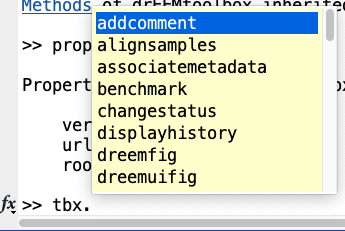

Now, say you know you want to look at your EEMs, but you don't remember that method's name. In drEEM, all visualization functions start with "view", so you can type tbx.view followed by the tab key (⇥). You'll see something like this: 

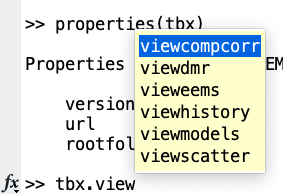

From there, it's pretty obvious that you'd select `tbx.vieweems` to take a look at your EEMs.

Ok, now you know how to remember the names of methods (aka functions). But what about that syntax? How do you get to do the thing you want to do with the function that you just found out about? drEEM has useful documentation in several different, accessible ways. I imagine you'd like to start by importing some data, right? But how? type `tbx.import` followed by the tab key (⇥) and you'll see that we have one function for EEMs and one for absorbance spectra. To get help with the synax, type for example

help tbx.importeems

--- help for drEEMtoolbox.importeems ---

  data = importeems(filePattern,options) (click to access documentation)
 
  Inputs - Required
  filePattern (1,:)                 {mustBeText}
  
  Inputs - Optional
  columnWave (1,:)          {mustBeNumericOrLogical} = true
  rowWave (1,:)             {mustBeNumericOrLogical} = true
  columnIsExcitation (1,:)  {mustBeNumericOrLogical}= true
  NumHeaderLines (1,1)      {mustBeNumeric}= 0
  waveDiffTollerance (1,1)  {mustBeNumeric} = 1



You get a basic reminder of the function syntax at the top, followed by a detailed list of input arguments, both required and optional with the defaults listed for the optional arguments. This is good if you know this function well. But if you don't, it's a good idea to read the in-depth documentation. Simply click on the hyperlink (blue) code that shows the basic syntax. You'll be taken to the full documentation.